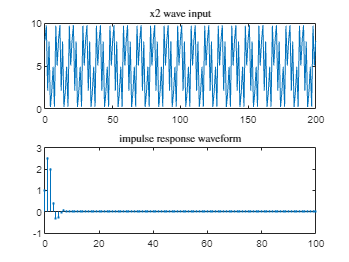

b=[1,2,1];a=[1,-0.5,0.25];
x=impseq(0,0,100);n=0:100;
h=filter(b,a,x);
stem(n,h,'.');title('impulse response waveform',Interpreter='latex');

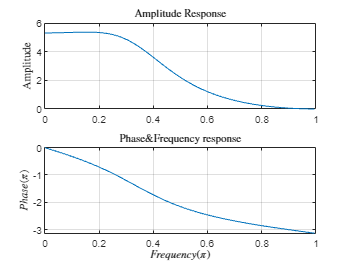

sum(abs(h));
figure;

[H,w]=freqz(b,a,200);
magH=abs(H);phaH=angle(H);
subplot(2,1,1),plot(w/pi,magH);grid
xlabel('');ylabel('Amplitude',Interpreter='latex');title('Amplitude Response',Interpreter='latex');
subplot(2,1,2);plot(w/pi,phaH);grid;
xlabel('$Frequency(\pi)$',Interpreter='latex');ylabel('$Phase(\pi)$',Interpreter='latex');title('Phase\&Frequency response',Interpreter='latex')

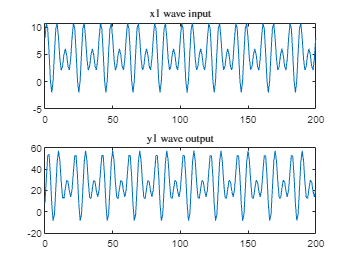

figure;

n1=0:200;
x1=5+3*cos(0.2*pi*n1)+4*sin(0.3*pi*n1);
y1=filter(b,a,x1);
subplot(2,1,1);plot(n1,x1);title('x1 wave input',Interpreter='latex');
subplot(2,1,2);plot(n1,y1);title('y1 wave output',Interpreter='latex');

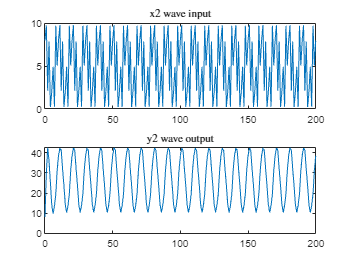

figure;

n1=0:200;
x2=5+3*cos(0.2*pi*n1)+4*sin(0.8*pi*n1);
y2=filter(b,a,x2);
subplot(2,1,1);plot(n1,x2);title('x2 wave input',Interpreter='latex');
subplot(2,1,2);plot(n1,y2);title('y2 wave output',Interpreter='latex');